load('C:\Users\Intel NUC Extreme\Documents\Files\code\Upperlimb_model_evaluation\data\forward_map_v1.mat')


ans =

     []


ans =

     []



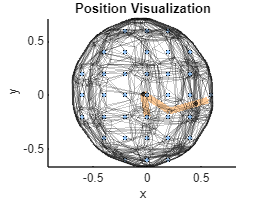

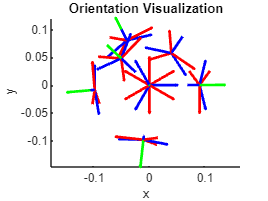

inverseMap =   InverseMap with properties:

      Domain: [1×1 SE3]
    Codomain: [1×1 Rn]


inverseMap = InverseMap(forwardMap)

range=[1,15];
[initialGuessList, matchCounter] = inverseMap.prefill(range);

updateCounter = inverseMap.iterate(initialGuessList,range);


ans =

     []


ans =

     []



save("data\inverse_map_v1_"+range(1)+"-"+range(2),"initialGuessList","inverseMap")